# Example One

Solve the following system of Ordinary Differential Equations.


$$\frac{dx}{dt} = x - y^{2}$$



$$\frac{dy}{dt} = 6$$


The initial conditions are $x(0) = 1$and $y(0) = 3$

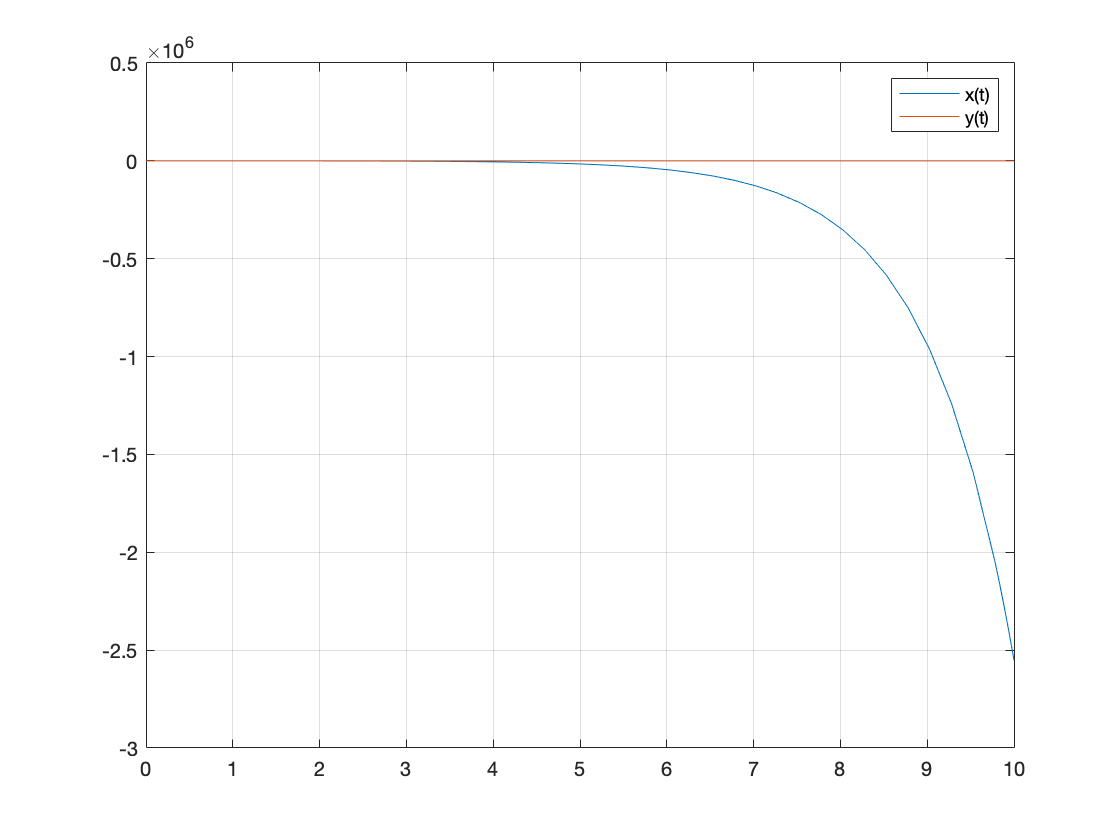

tRange = [0 10];
Z0 = [1;3];
[tSol,ZSol] = ode45(@mySystem,tRange,Z0);
plot(tSol,ZSol(:,1),tSol,ZSol(:,2)); grid on
legend('x(t)','y(t)')

#### ODEs System Function

function dzdt = mySystem(t,Z)
x = Z(1);
y = Z(2);

dxdt = x - y.^2;
dydt = 6;

dzdt = [dxdt;dydt];

end